## Filter Testing

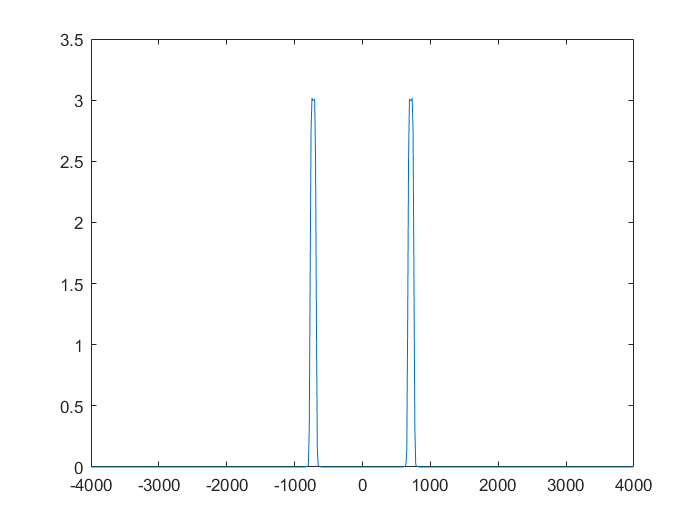

% For testing the filter before implementing into main

N = 5000;
Fs = 8000;
load audioclip.mat;

clear sound
Fc1=675; % cutoff freq 1
Fc2=765;
L=303; % number of coefficients, 91 || 171 work well
n=0:2*L;
attenuation_factor = 3;
h_w_1=2*Fc1/Fs*sinc(2*Fc1/Fs*(n-L)) * attenuation_factor;
h_w_2=2*Fc2/Fs*sinc(2*Fc2/Fs*(n-L)) * attenuation_factor;
hann_window = 1/2*(1-cos(2*pi*n/(2*L)));
h_hann_1 = h_w_1 .* hann_window;
h_hann_2 = h_w_2 .* hann_window;
h_LPF = h_hann_2 - h_hann_1;
H_LPF = fft(h_LPF);
F_filter = -Fs/2:Fs/length(H_LPF):(length(H_LPF)-1)*Fs/(2*length(H_LPF));
plot(F_filter, fftshift(abs(H_LPF)));

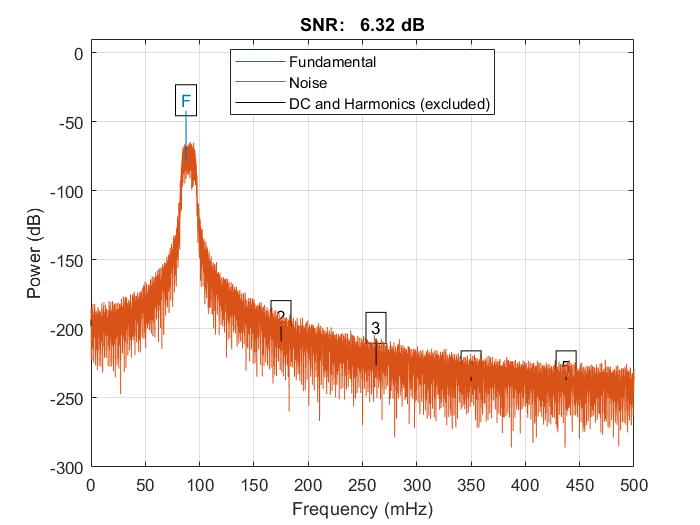

ans = 6.3231


% Filter test
noise = audio + 0.01*randn(length(audio),1);
filteredSignal = conv(h_LPF, noise);
filteredSignalTransform = fft(filteredSignal, N)/N;
% sound(filteredSignal)
snr(filteredSignal)

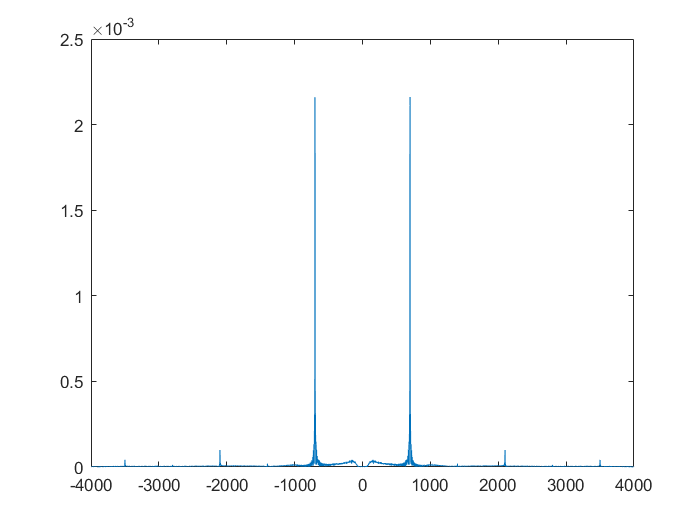


% Original audio
X_f = fft(audio, N)/N;
F = -Fs/2:Fs/N:(N-1)*Fs/(2*N);
X_f_db = 10*log(abs(X_f));
X_omg = fftshift(abs(X_f));
plot(F, X_omg)